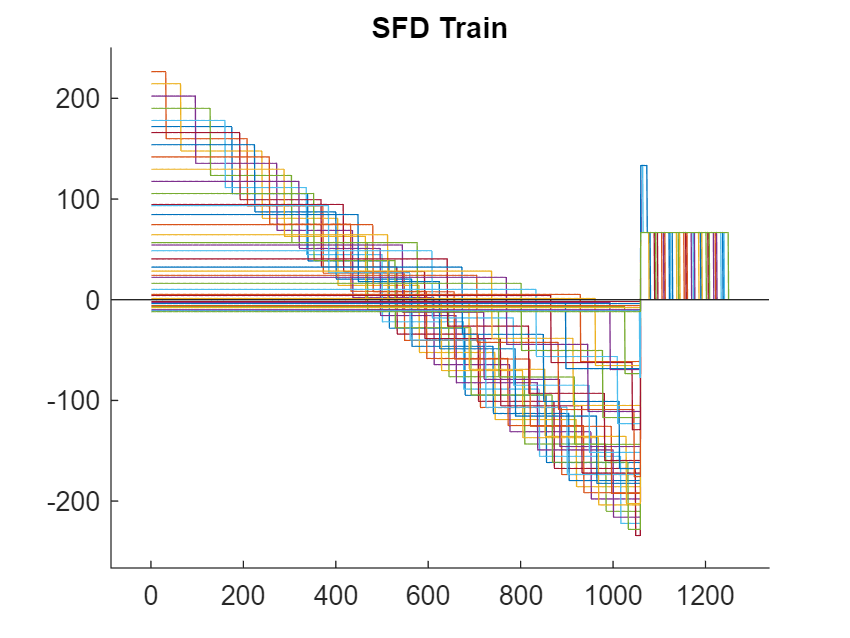

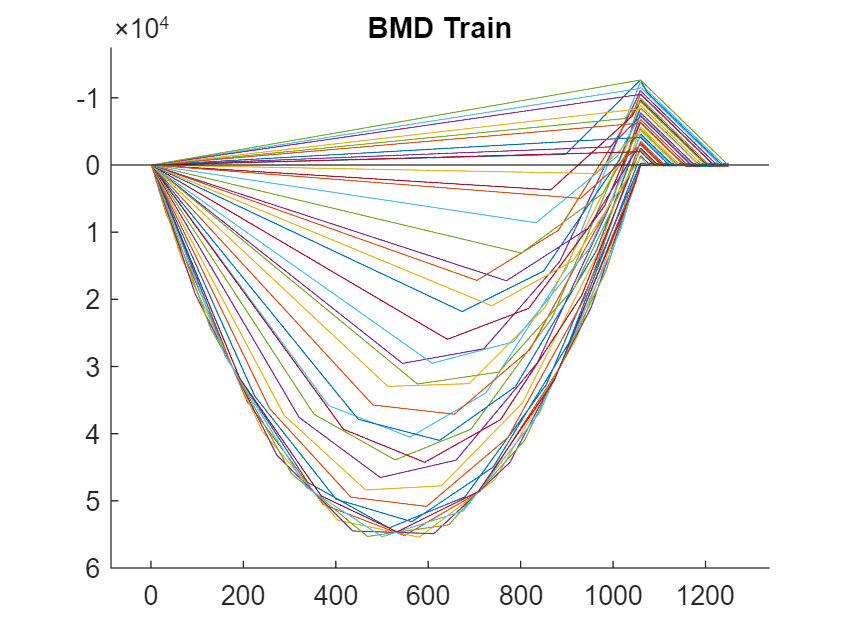

clear
close all
%% 0. Initialize Parameters 
n = 1250;                  % Number of locations to evaluate bridge failure 
L = 1250;                  % Length of bridge 
  
x = linspace(0, L, n);     % Define x coordinate 

[maxShear, minShear, maxMoment,minMoment] = trainData(L);

%% 2. Define cross-sections for design 0
height = 120; % side flang
thik = 1.27;
tf = 110;
bf = 70;
stickPart = 10;

a = [120,120,90,90,75,75]; %Largest Distance
a_x = [0,499,500,999,1000,1250];

%% 3. Define Material Properties 
SigT = 30; 
SigC = 6; 
E    = 4000;
TauU = 4; 
TauG = 2; 
mu   = 0.2; 

[ybar_x,I_x,Q_x,QGlue_x1,QGlue_x2,ytop,ybot] = SectionProperties(thik,tf,height,bf,stickPart,n);
V_Mat = Vfail(I_x,Q_x,TauU,thik);
[V_Glue1,V_Glue2] = VfailGlue(I_x,QGlue_x1,QGlue_x2,TauG);
V_Buck = VfailBuck(I_x,Q_x,thik, height, E, mu,a,a_x,x);
  
[M_MatT_Max,M_MatT_Min] = MfailMatT(maxMoment,minMoment,I_x, ybot, ytop,SigT,x); 
[M_MatC_Max,M_MatC_Min] = MfailMatC(maxMoment,minMoment,I_x, ybot, ytop,SigC,x); 
[M_Buck1_Max,M_Buck1_Min] = MfailBuck1(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x); 
[M_Buck2_Max,M_Buck2_Min] = MfailBuck2(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x,tf); 
[M_Buck3_Max,M_Buck3_Min] = MfailBuck3(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x,tf); 

[ Min_FOS ] = FOS(maxShear, minShear, maxMoment,minMoment,V_Mat,V_Glue1,V_Glue2,V_Buck,M_MatT_Max,M_MatT_Min,M_MatC_Max,M_MatC_Min,M_Buck1_Max,M_Buck1_Min,M_Buck2_Max,M_Buck2_Min,M_Buck3_Max,M_Buck3_Min)

Min_FOS = 2.7274

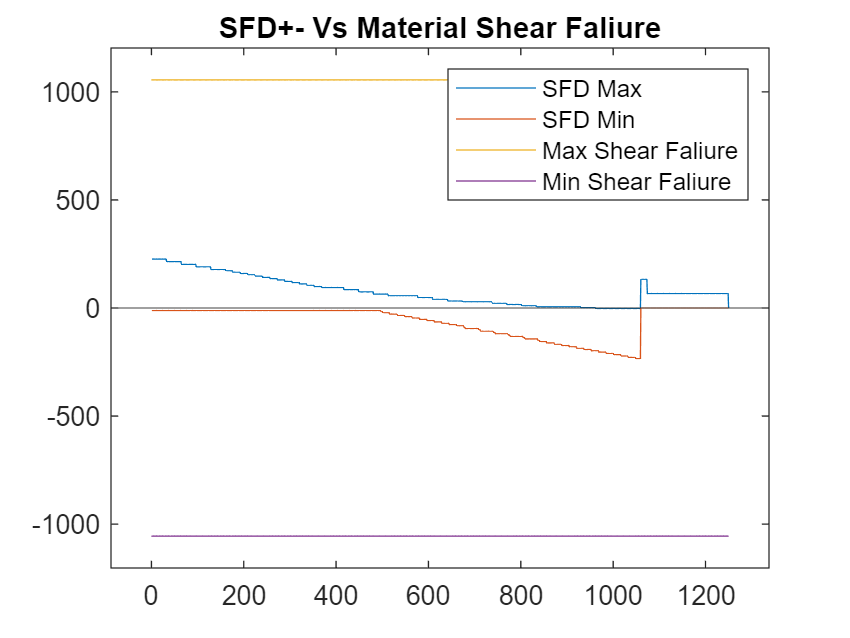


figure(3)
plot(1:L,maxShear)
hold on
plot(1:L,minShear)
plot(x,V_Mat)
plot(x,-V_Mat)
axis padded
yline(0,'-')
title("SFD+- Vs Material Shear Faliure")
legend(["SFD Max","SFD Min","Max Shear Faliure","Min Shear Faliure"],"location","northeast")

hold off

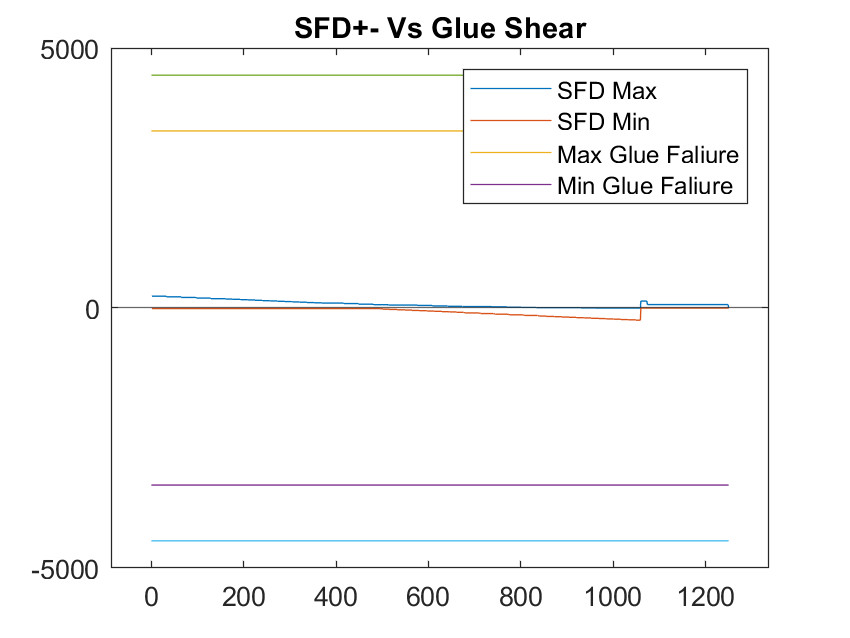

figure(4)
plot(1:L,maxShear)
hold on
plot(1:L,minShear)
plot(x,V_Glue1)
plot(x,-V_Glue1)
plot(x,V_Glue2)
plot(x,-V_Glue2)
axis padded
yline(0,'-')
title("SFD+- Vs Glue Shear")
legend(["SFD Max","SFD Min","Max Glue Faliure","Min Glue Faliure"],"location","northeast")

hold off

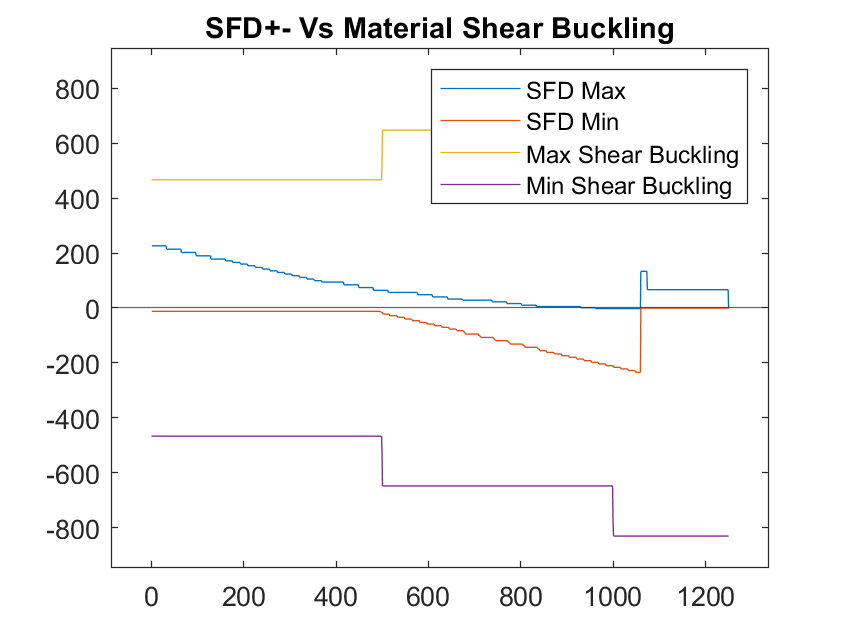

figure(5)
plot(1:L,maxShear)
hold on
plot(1:L,minShear)
plot(x,V_Buck)
plot(x,-V_Buck)
axis padded
yline(0,'-')
title("SFD+- Vs Material Shear Buckling")
legend(["SFD Max","SFD Min","Max Shear Buckling","Min Shear Buckling"],"location","northeast")

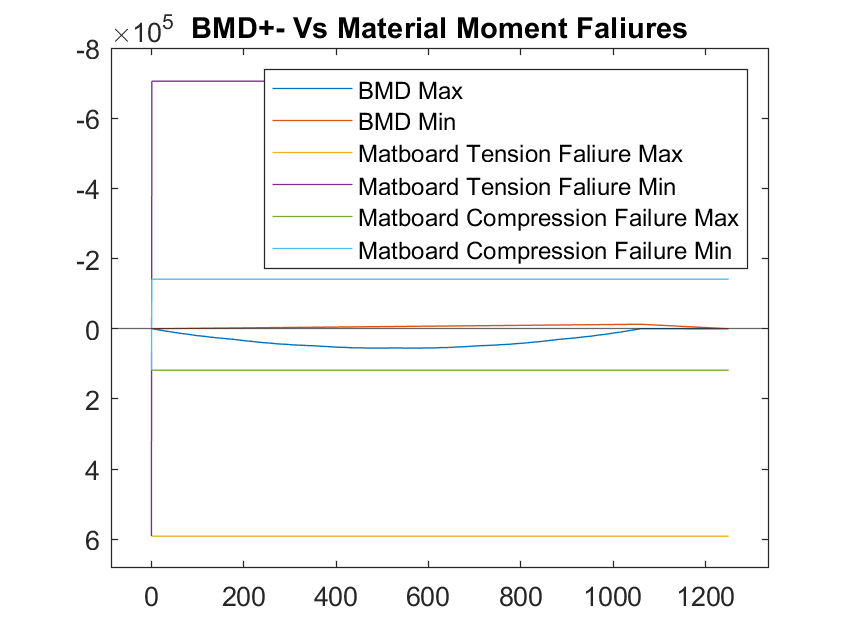


figure(6)
hold off
plot(1:L,maxMoment)
hold on
plot(1:L,minMoment)
plot(x,M_MatT_Max)
plot(x,M_MatT_Min)
plot(x,M_MatC_Max)
plot(x,M_MatC_Min)
axis padded
yline(0,'-')
set(gca, 'YDir','reverse')
title("BMD+- Vs Material Moment Faliures")
legend(["BMD Max","BMD Min","Matboard Tension Faliure Max","Matboard Tension Faliure Min","Matboard Compression Failure Max","Matboard Compression Failure Min"],"location","northeast")

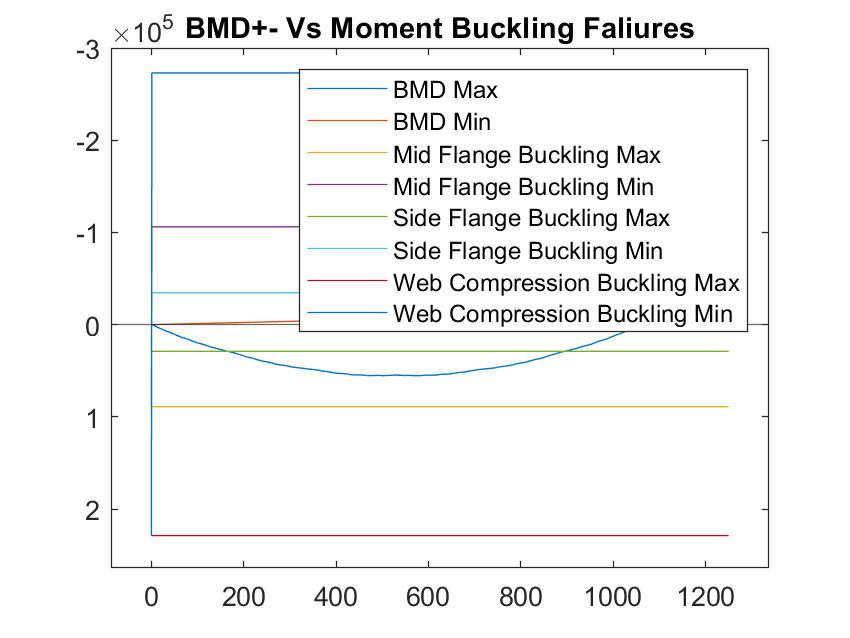


figure(7)
hold off
plot(1:L,maxMoment)
hold on
plot(1:L,minMoment)
plot(x,M_Buck1_Max)
plot(x,M_Buck1_Min)
plot(x,M_Buck2_Max)
plot(x,M_Buck2_Min)
plot(x,M_Buck3_Max)
plot(x,M_Buck3_Min)
axis padded
yline(0,'-')
set(gca, 'YDir','reverse')
title("BMD+- Vs Moment Buckling Faliures")
legend(["BMD Max","BMD Min","Mid Flange Buckling Max","Mid Flange Buckling Min","Side Flange Buckling Max","Side Flange Buckling Min","Web Compression Buckling Max","Web Compression Buckling Min"])

function[maxShear, minShear, maxMoment,minMoment] = trainData(L);
    pointLoad = [66.7 66.7 66.7 66.7 66.7 66.7];
    maxMoment = -10000000*ones(L,1);
    minMoment = 100000000*ones(L,1);

    maxShear = -10000000*ones(L,1);
    minShear = 100000000*ones(L,1);

    for i = linspace(0,L,40)
        pointLoad_Locations = [0,176,340,516,680,856]+i;
        [sfd,bmd] = PointLoads(pointLoad_Locations, pointLoad,L);
        
        maxMoment = max(maxMoment, bmd);
        minMoment = min(minMoment,bmd);

        maxShear = max(maxShear, sfd);
        minShear = min(minShear,sfd);
        
        figure(1)
        hold on
        plot(1:L,sfd)
        axis padded
        yline(0,'-')
        title("SFD Train")
        hold off

        figure(2)
        hold on
        plot(1:L,bmd)
        set(gca, 'YDir','reverse')
        axis padded
        yline(0,'-')
        title("BMD Train")
        hold on
    end
end

function [sfdGraph , bmdGraph] = PointLoads(pointLoad_Locations,pointLoad,L)
reactionBDisToA = 1060;

for i = 1:length(pointLoad_Locations)
    if pointLoad_Locations(i) > L
        pointLoad(i) = 0;
    end
end

By = sum(pointLoad_Locations .* pointLoad)/reactionBDisToA;
Ay = sum(pointLoad)-By;


sfdPointLoads = [Ay, ...
                -pointLoad(pointLoad_Locations <= reactionBDisToA), ...
                By, ...
                -pointLoad(pointLoad_Locations > reactionBDisToA)];%I made point loads negative

sfdPointLocations = [0, ...
                    pointLoad_Locations(pointLoad_Locations <= reactionBDisToA), ...
                    reactionBDisToA, ...
                    pointLoad_Locations(pointLoad_Locations > reactionBDisToA)];

sfd = cumsum(sfdPointLoads);


sfdGraph = zeros(L,1);
for i=1:L
    sfdGraph(i) = sfd(find(sfdPointLocations <= i, 1, 'last'));
end

bmdGraph = cumtrapz(sfdGraph);
end


function [ybar_x,I_x,Q_x,QGlue_x1,QGlue_x2,ytop,ybot] = SectionProperties(thik,tf,height,bf,stickPart,n)
Areas = zeros(8,1);
ydistance = zeros(8,1);
IValues = zeros(8,1);
dValues = zeros(8,1);
% Calculates important sectional properties. Including but not limited to ybar, I, Q, etc. 
% Input: Geometric Inputs. Format will depend on user 
% Output: Sectional Properties at every value of x. Each property is a 1-D array of length n 
Areas(1) = tf * thik;
ydistance(1) = height - (thik/2);

Areas(2) = bf * thik;
ydistance(2) = (thik/2);

Areas(3) =  (height + (thik*-4)) * thik;
ydistance(3) = ((0.5*((height + (thik*-4))))+ 2*thik);

Areas(4) = (height + (thik*-4)) * thik;
ydistance(4) = ((0.5*((height + (thik*-4))))+ 2*thik);

Areas(5) = (stickPart * thik);
ydistance(5) = height - thik - (thik/2);

Areas(6) = (stickPart * thik);
ydistance(6) = height - thik - (thik/2);

Areas(7) = (stickPart * thik);
ydistance(7) = thik + (thik/2);

Areas(8) = (stickPart * thik);
ydistance(8) = thik + (thik/2);

ybarTop = 0;
ybarBot = 0;

for i = 1:8
    ybarTop = ybarTop + Areas(i)*ydistance(i);
    ybarBot = ybarBot + Areas(i);
end

ybar = ybarTop/ybarBot;
ybar_x = ybar * ones(1,n);

IValues(1) = (tf * thik^3)/12;
IValues(2) = (bf * thik^3)/12;
IValues(3) = (thik * (height-(thik*4))^3)/12;
IValues(4) = (thik * (height-(thik*4))^3)/12;
IValues(5) = (stickPart * thik^3)/12;
IValues(6) = (stickPart * thik^3)/12;
IValues(7) = (stickPart * thik^3)/12;
IValues(8) = (stickPart * thik^3)/12;

dValues(1) = height - ybar - (thik/2);
dValues(2) = ybar - (thik/2);
dValues(3) = ybar - (((height - thik*4)/2)+2*thik);
dValues(4) = ybar - (((height - thik*4)/2)+2*thik);

dValues(5) = (height - thik - (thik/2)) - ybar;
dValues(6) = (height - thik - (thik/2)) - ybar;
dValues(7) = ybar - (thik - (thik/2));
dValues(8) = ybar - (thik - (thik/2));

I = 0;
for i = 1:8
    I = I + IValues(i) + Areas(i)*(dValues(i))^2;
end
I_x = I .* ones(1,n);

Q = (Areas(2)*dValues(2)) + 2*(((ybar - 2*thik) * thik)*(ybar - 2*thik)/2) + 2*(Areas(6) * (ybar -thik/2));
Q_x = Q .* ones(1,n);

QGlue1 = Areas(1)*dValues(1);
QGlue_x1 = QGlue1 .* ones(1,n);

QGlue2 = Areas(2)*dValues(2);
QGlue_x2 = QGlue2 .* ones(1,n);

ytop = (height - ybar_x) .* ones(1,n);
ybot = (ybar_x) .* ones(1,n);
end


function [ V_fail ] = Vfail(I_x,Q_x,TauU,thik) 
% Calculates shear forces at every value of x that would cause a matboard shear failure 
% Input: Sectional Properties (list of 1-D arrays), TauU (scalar material property) 
% Output: V_fail a 1-D array of length n  
    b = thik * 2; %%%%Change for diffrent cross section
 
    V_fail = TauU .* I_x .* b ./ Q_x;  
end 

function [V_Glue1,V_Glue2] = VfailGlue(I_x,QGlue_x1,QGlue_x2,TauG);
    b = 10; %Glue Area Design0 %%%%Change for diffrent cross section
 
    V_Glue1 = TauG .* I_x .* b ./ QGlue_x1;  
    V_Glue2 = TauG .* I_x .* b ./ QGlue_x2;  
end

function [V_Buck] = VfailBuck(I_x,Q_x,thik, height, E, mu,a,a_x,x)
    b = thik;
    a_s = interp1(a_x,a,x);
    TauBuck = ((5*pi^2*E)/12*(1-mu^2)) .* ((thik./a_s).^2 + (thik/height)^2);
    V_Buck = TauBuck .* I_x .* b ./ Q_x;  
end

function [M_MatT_Max,M_MatT_Min] = MfailMatT(maxMoment,minMoment,I_x, ybot, ytop,SigT,x)
% Calculates bending moments at every value of x that would cause a matboard tension failure 
% Input: Sectional Properties (list of 1-D arrays), SigT (material property), BMD (1-D array) 
% Output: M_MatT a 1-D array of length n 
for i = 1 : length(x) 

    if maxMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_MatT_Max(i) = SigT * I_x(i) / ybot(i); 
    elseif maxMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
             M_MatT_Max(i) = -SigT * I_x(i) / ytop(i); 
    end 

    if minMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_MatT_Min(i) = SigT * I_x(i) / ybot(i); 
    elseif minMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_MatT_Min(i) = -SigT * I_x(i) / ytop(i); 
    end 
end
end

function [M_MatC_Max,M_MatC_Min] = MfailMatC(maxMoment,minMoment,I_x, ybot, ytop,SigC,x)
for i = 1 : length(x) 
    if maxMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
        M_MatC_Max(i) = SigC * I_x(i) / ybot(i); 
    elseif maxMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
         M_MatC_Max(i) = -SigC * I_x(i) / ytop(i); 
    end 
    
    if minMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
        M_MatC_Min(i) = SigC * I_x(i) / ybot(i); 
    elseif minMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
         M_MatC_Min(i) = -SigC * I_x(i) / ytop(i); 
    end  
end
end

function [M_Buck1_Max,M_Buck1_Min] = MfailBuck1(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x)
    b = bf;
    stressBuck1 = ((4*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if maxMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck1_Max(i) = stressBuck1*I_x(i)/ybot(i);
        elseif maxMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck1_Max(i) = -stressBuck1*I_x(i)/ytop(i);
        end 

          if minMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck1_Min(i) = stressBuck1*I_x(i)/ybot(i);
        elseif minMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck1_Min(i) = -stressBuck1*I_x(i)/ytop(i);
        end 
    end 
end

function [M_Buck2_Max,M_Buck2_Min] = MfailBuck2(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x,tf)
    b = tf-bf;
    stressBuck2 = ((0.425*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if maxMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck2_Max(i) = stressBuck2*I_x(i)/ybot(i);
        elseif maxMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck2_Max(i) = -stressBuck2*I_x(i)/ytop(i);
        end 

        if minMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck2_Min(i) = stressBuck2*I_x(i)/ybot(i);
        elseif minMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck2_Min(i) = -stressBuck2*I_x(i)/ytop(i);
        end 
    end 
end

function [M_Buck3_Max,M_Buck3_Min] = MfailBuck3(maxMoment,minMoment,I_x,thik, E, mu, ytop,ybot,bf,x,tf)
    b = ytop-thik; %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% I am not sure what b should be
    stressBuck3 = ((6*pi^2*E)/(12*(1-mu^2))) .* ((thik./b).^2);

    for i = 1 : length(x) 
        if maxMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck3_Max(i) = stressBuck3(i)*I_x(i)/ybot(i);
        elseif maxMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck3_Max(i) = -stressBuck3(i)*I_x(i)/ytop(i);
        end 

        if minMoment(i) >= 0 % If the moment is positive, the tension failure will be at the bottom 
            M_Buck3_Min(i) = stressBuck3(i)*I_x(i)/ybot(i);
        elseif minMoment(i) < 0 % If the moment is negative, the tension failure will be at the top 
            M_Buck3_Min(i) = -stressBuck3(i)*I_x(i)/ytop(i);
        end 
    end 
end

function [ Min_FOS ] = FOS(maxShear, minShear, maxMoment,minMoment,V_Mat,V_Glue1,V_Glue2,V_Buck,M_MatT_Max,M_MatT_Min,M_MatC_Max,M_MatC_Min,M_Buck1_Max,M_Buck1_Min,M_Buck2_Max,M_Buck2_Min,M_Buck3_Max,M_Buck3_Min)
        FosVMat_Max = max (abs(V_Mat./maxShear'));
        FosV_Glue1_Max = max (abs(V_Glue1./maxShear'));
        FosV_Glue2_Max = max (abs(V_Glue2./maxShear'));
        FosV_Buck_Max = max (abs(V_Buck./maxShear'));
        FosM_MatT_Max = max (abs(M_MatT_Max./maxMoment'));
        FosM_MatC_Max = max (abs(M_MatC_Max./maxMoment'));
        FosM_Buck1_Max = max (abs(M_Buck1_Max./maxMoment'));
        FosM_Buck2_Max = max (abs(M_Buck2_Max./maxMoment'));
        FosM_Buck3_Max = max (abs(M_Buck3_Max./maxMoment'));

        FosVMat_Min = min (abs(V_Mat./minShear'));
        FosV_Glue1_Min = min (abs(V_Glue1./minShear'));
        FosV_Glue2_Min = min (abs(V_Glue2./minShear'));
        FosV_Buck_Min = min (abs(V_Buck./minShear'));
        FosM_MatT_Min = min (abs(M_MatT_Min./minMoment'));
        FosM_MatC_Min = min (abs(M_MatC_Min./minMoment'));
        FosM_Buck1_Min = min (abs(M_Buck1_Min./minMoment'));
        FosM_Buck2_Min = min (abs(M_Buck2_Min./minMoment'));
        FosM_Buck3_Min = min (abs(M_Buck3_Min./minMoment'));

        Min_FOS = min([FosVMat_Max,FosV_Glue1_Max,FosV_Glue2_Max,FosV_Buck_Max,FosM_MatT_Max,FosM_MatC_Max,FosM_Buck1_Max,FosM_Buck2_Max,FosM_Buck3_Max,...
                      FosVMat_Min,FosV_Glue1_Min,FosV_Glue2_Min,FosV_Buck_Min,FosM_MatT_Min,FosM_MatC_Min,FosM_Buck1_Min,FosM_Buck2_Min,FosM_Buck3_Min]);
end
